# U.S. Macroeconomic Outlook: Forecasts and Business-Cycle Dynamics

This report examines U.S. business-cycle dynamics and the recovery outlook following the 2008 financial crisis. An eight-variable macroeconomic model evaluates historical forecast performance and compares projections at year-end 2008 with those at the end of the observation period.

The specification draws on the macroeconomic variables considered by Smets and Wouters. An unrestricted vector autoregression (VAR) captures their joint dynamics, with particular attention to the effects of the 2008 financial crisis.

## Modeling Framework

The Smets-Wouters model (2002, 2004, 2007) describes an economy through a nonlinear system of dynamic stochastic general equilibrium (DSGE) equations. Its seven core time series are output, prices, wages, hours worked, interest rates, consumption, and investment.

This framework favors a compact specification grounded in economic theory over a large set of empirically motivated regressions. The combination of theoretical structure and parsimony motivates the variable selection here.

The linearized form can be represented as a VAR. The analysis below estimates an unrestricted specification to examine the relationships among these macroeconomic series.

Unemployment is included as an eighth variable to track labor-market conditions. It is outside the basic Smets-Wouters specification and is superfluous within that framework, but provides a widely followed measure of economic conditions.

The original framework was developed for individual and aggregate European economies. This analysis applies it to the United States, following the setting of Smets and Wouters (2007).

## Data Sources and Coverage

The analysis draws on the Federal Reserve Bank of St. Louis economic database (FRED). The historical sample spans 1947 Q1 through 2009 Q1, placing the financial crisis in the context of six decades of U.S. economic activity. Joint coverage across all 14 source series begins in 1959 Q1. The series and their definitions are listed below.

% FRED Series     Description
% -----------     ----------------------------------------------------------------
% COE             Paid compensation of employees in $ billions
% CPIAUCSL        Consumer price index
% FEDFUNDS        Effective federal funds rate
% GCE             Government consumption expenditures and investment in $ billions
% GDP             Gross domestic product in $ billions
% GDPDEF          Gross domestic product price deflator
% GPDI            Gross private domestic investment in $ billions
% GS10            Ten-year treasury bond yield
% HOANBS          Non-farm business sector index of hours worked
% M1SL            M1 money supply (narrow money)
% M2SL            M2 money supply (broad money)
% PCEC            Personal consumption expenditures in $ billions
% TB3MS           Three-month treasury bill yield
% UNRATE          Unemployment rate

The series are aligned to a quarterly observation period. Monthly indicators are measured in the final month of each quarter, while quarterly indicators retain their reported values. Estimation uses only quarters with observations for every source series, ensuring a common sample across the model variables.

The historical data vintage anchors the crisis-era outlook. Revised observations can change estimated relationships and forecast paths, so comparisons across observation periods should account for both the information available at the forecast origin and subsequent data revisions.

rng(0,'twister')
try
    cd(fileparts(matlab.desktop.editor.getActiveFilename));
catch
end
datasetFile = "data/us_macro_original_1947_2009.mat";
addpath(fullfile(pwd,'data'));
macroDataset = load_us_macro_data(datasetFile);
series = macroDataset.series;
dates = macroDataset.dates;
Data = macroDataset.Data;
DataTable = macroDataset.DataTable;
DataProvenance = macroDataset.Provenance;

## Business-Cycle Chronology

National Bureau of Economic Research (NBER) peak and trough dates identify recession periods for comparison with the model results (see references). Recession boundaries are assigned to the middle of the reported month.

Recessions = [ datenum('15-May-1937'), datenum('15-Jun-1938');
    datenum('15-Feb-1945'), datenum('15-Oct-1945');
    datenum('15-Nov-1948'), datenum('15-Oct-1949');
    datenum('15-Jul-1953'), datenum('15-May-1954');
    datenum('15-Aug-1957'), datenum('15-Apr-1958');
    datenum('15-Apr-1960'), datenum('15-Feb-1961');
    datenum('15-Dec-1969'), datenum('15-Nov-1970');
    datenum('15-Nov-1973'), datenum('15-Mar-1975');
    datenum('15-Jan-1980'), datenum('15-Jul-1980');
    datenum('15-Jul-1981'), datenum('15-Nov-1982');
    datenum('15-Jul-1990'), datenum('15-Mar-1991');
    datenum('15-Mar-2001'), datenum('15-Nov-2001');
    datenum('15-Dec-2007'), datenum('15-Jun-2009') ];

Recessions = busdate(Recessions);

## Data Transformations

Two representations support the analysis: differenced or rate series for model estimation, and integrated or cumulative series for forecast evaluation. Series with exponential growth are transformed to logarithms before differencing.

% Remove dates with NaN values

ii = any(isnan(Data),2);
dates(ii) = [];
Data(ii,:) = [];
DataTable(ii,:) = [];

% Log series

CONS = log(DataTable.PCEC);
CPI = log(DataTable.CPIAUCSL);
DEF = log(DataTable.GDPDEF);
GCE = log(DataTable.GCE);
GDP = log(DataTable.GDP);
HOURS = log(DataTable.HOANBS);
INV = log(DataTable.GPDI);
M1 = log(DataTable.M1SL);
M2 = log(DataTable.M2SL);
WAGES = log(DataTable.COE);

% Interest rates (annual)

rFED = 0.01*(DataTable.FEDFUNDS);
rG10 = 0.01*(DataTable.GS10);
rTB3 = 0.01*(DataTable.TB3MS);

% Integrated rates

FED = ret2tick(0.25*rFED);
FED = log(FED(2:end));
G10 = ret2tick(0.25*rG10);
G10 = log(G10(2:end));
TB3 = ret2tick(0.25*rTB3);
TB3 = log(TB3(2:end));

% Unemployment rate

rUNEMP = 0.01*(DataTable.UNRATE);

UNEMP = ret2tick(0.25*rUNEMP);
UNEMP = log(UNEMP(2:end));

% Annualized rates

rCONS = [ 4*mean(diff(CONS(1:5))); 4*diff(CONS) ];
rCPI = [ 4*mean(diff(CPI(1:5))); 4*diff(CPI) ];
rDEF = [ 4*mean(diff(DEF(1:5))); 4*diff(DEF) ];
rGCE = [ 4*mean(diff(GCE(1:5))); 4*diff(GCE) ];
rGDP = [ 4*mean(diff(GDP(1:5))); 4*diff(GDP) ];
rHOURS = [ 4*mean(diff(HOURS(1:5))); 4*diff(HOURS) ];
rINV = [ 4*mean(diff(INV(1:5))); 4*diff(INV) ];
rM1 = [ 4*mean(diff(M1(1:5))); 4*diff(M1) ];
rM2 = [ 4*mean(diff(M2(1:5))); 4*diff(M2) ];
rWAGES = [ 4*mean(diff(WAGES(1:5))); 4*diff(WAGES) ];

## Macroeconomic Indicators

The indicator panels provide context for the estimation and forecast results. Transformed series, identified by the lowercase r prefix, are plotted alongside shaded NBER recession periods.

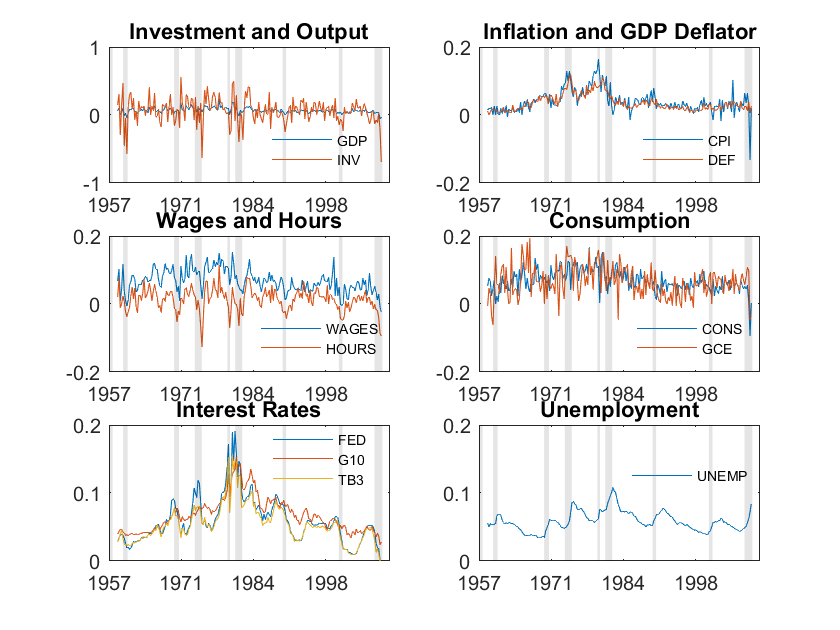

clf;

subplot(3,2,1,'align');
plot(dates, [rGDP, rINV]);
recessionplot;
dateaxis('x');
title('\bfInvestment and Output');
h = legend('GDP','INV','Location','Best');
h.FontSize = 7;
h.Box = 'off';
axis([dates(1) - 600, dates(end) + 600, 0, 1]);
axis 'auto y'

subplot(3,2,2,'align');
plot(dates, [rCPI, rDEF]);
recessionplot;
dateaxis('x');
title('\bfInflation and GDP Deflator');
h = legend('CPI','DEF','Location','Best');
h.FontSize = 7;
h.Box = 'off';
axis([dates(1) - 600, dates(end) + 600, 0, 1]);
axis 'auto y'

subplot(3,2,3,'align');
plot(dates, [rWAGES, rHOURS]);
recessionplot;
dateaxis('x');
title('\bfWages and Hours');
h = legend('WAGES','HOURS','Location','Best');
h.FontSize = 7;
h.Box = 'off';
axis([dates(1) - 600, dates(end) + 600, 0, 1]);
axis 'auto y'

subplot(3,2,4,'align');
plot(dates, [rCONS, rGCE]);
recessionplot;
dateaxis('x');
title('\bfConsumption');
h = legend('CONS','GCE','Location','Best');
h.FontSize = 7;
h.Box = 'off';
axis([dates(1) - 600, dates(end) + 600, 0, 1]);
axis 'auto y'

subplot(3,2,5,'align');
plot(dates, [rFED, rG10, rTB3]);
recessionplot;
dateaxis('x');
title('\bfInterest Rates');
h = legend('FED','G10','TB3','Location','Best');
h.FontSize = 7;
h.Box = 'off';
axis([dates(1) - 600, dates(end) + 600, 0, 1]);
axis 'auto y'

subplot(3,2,6,'align');
plot(dates, rUNEMP);
recessionplot;
dateaxis('x');
title('\bfUnemployment');
h = legend('UNEMP','Location','Best');
h.FontSize = 7;
h.Box = 'off';
axis([dates(1) - 600, dates(end) + 600, 0, 1]);
axis 'auto y'

## Model Variables

The estimation dataset contains the seven series considered by Smets and Wouters (2007), together with unemployment. The mapping from FRED data to model variables is shown below. Growth rates and changes describe short-term dynamics, while cumulative paths support comparisons of projected and realized outcomes.

%   Model       FRED Series     Transformation from FRED Data to Model Time Series
%   --------    -----------     --------------------------------------------------
%   rGDP        GDP             rGDP = diff(log(GDP))
%   rDEF        GDPDEF          rDEF = diff(log(GDPDEF))
%   rWAGES      COE             rWAGE = diff(log(COE))
%   rHOURS      HOANBS          rWORK = diff(log(WORK))
%   rTB3        TB3MS           rTB3 = 0.01*TB3MS
%   rCONS       PCEC            rCONS = diff(log(PCEC))
%   rINV        GPDI            rINV = diff(log(GPDI))
%   rUNEMP      UNRATE          rUNEMP = 0.01*UNRATE

Y = [rGDP, rDEF, rWAGES, rHOURS, rTB3, rCONS, rINV, rUNEMP];
iY = [GDP, DEF, WAGES, HOURS, TB3, CONS, INV, UNEMP];

YSeries = {'Output (GDP)', 'Prices', 'Total Wages', 'Hours Worked', ...
    'Cash Rate', 'Consumption', 'Private Investment', 'Unemployment'};
YAbbrev = {'GDP', 'DEF', 'WAGES', 'HOURS', 'TB3', 'CONS', 'INV', 'UNEMP'};

YInfo = 'U.S. Macroeconomic Model';

n = numel(YSeries);

fprintf('The date range for available data is %s to %s.\n', ...
    datestr(dates(1),1),datestr(dates(end),1));

The date range for available data is 31-Mar-1959 to 31-Mar-2009.


## Model Specification

Joint macroeconomic dynamics are represented by an unrestricted VAR of the form


$$
 \textbf{Y}_t = \textbf{a} + \sum_{i = 1}^p \textbf{A}_i \textbf{Y}_{t - i} + \textbf{W}_t
$$


with


$$
 \textbf{Y}_t = \left[ \begin{array}{c}
 rGDP_t \\
 rDEF_t \\
 rWAGES_t \\
 rHOURS_t \\
 rTB3_t \\
 rCONS_t \\
 rINV_t \\
 rUNEMP_t \\
 \end{array} \right]
$$


and


$$
 \textbf{W}_t \sim N(\textbf{0}, \textbf{Q}) .
$$


Several choices distinguish this specification from the Smets-Wouters model. Nominal series are retained because the GDP deflator is included. The three-month Treasury bill rate replaces the federal funds rate for its longer coverage. Hours worked enter in changes rather than integrated form, unemployment is added, and the data are not detrended using individual trends or a common GDP trend.

## Lag-Length Assessment

The Akaike Information Criterion (AIC) is evaluated for specifications with one through seven quarterly lags. The lowest AIC identifies the preferred lag length under this criterion. Theory suggests around three lags, while empirical practice commonly uses two to four. The subsequent backtest and forecasts use a two-lag specification.

nARmax = 7;

Y0 = Y(1:nARmax,:);
Y1 = Y(nARmax+1:end,:);

AICtest = zeros(nARmax,1);
for i = 1:nARmax
    Spec = vgxset('n', n, 'Constant', true, 'nAR', i, 'Series', YSeries);
    [Spec, SpecStd, LLF] = vgxvarx(Spec, Y1, [], Y0);
    AICtest(i) = aicbic(LLF,Spec.NumActive,Spec.T);
    fprintf('AIC(%d) = %g\n',i,AICtest(i));
end

AIC(1) = -8438.02


AIC(2) = -8459.85


AIC(3) = -8435.67


AIC(4) = -8424


AIC(5) = -8407.53


AIC(6) = -8387.65


AIC(7) = -8337.47


[AICmin, nAR] = min(AICtest);

fprintf('Optimal lag for model is %d.\n',nAR);

Optimal lag for model is 2.


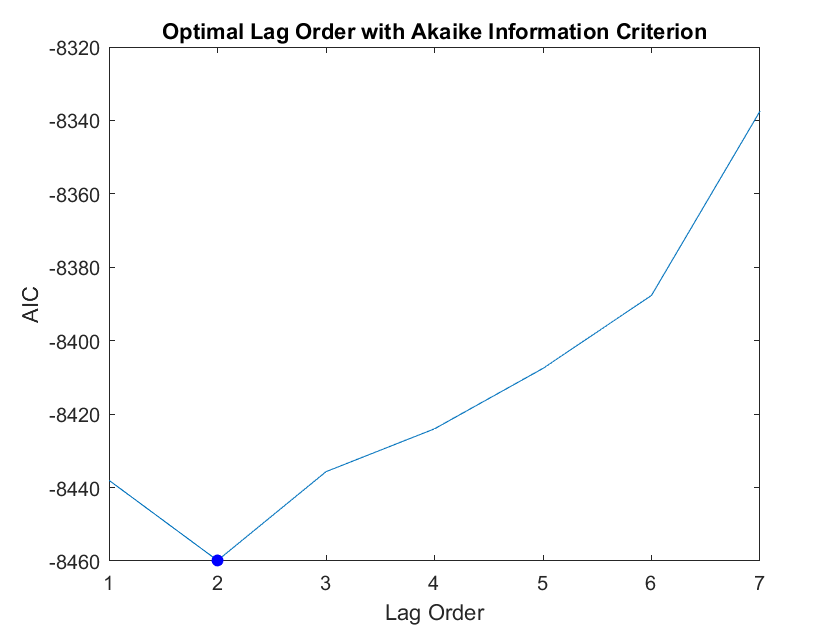


clf;

plot(AICtest);
hold on
scatter(nAR,AICmin,'filled','b');
title('\bfOptimal Lag Order with Akaike Information Criterion');
xlabel('Lag Order');
ylabel('AIC');
hold off

## Forecast Backtest

Forecast performance is evaluated at annual forecast origins from 1975 through 2008. Each estimation is followed by a Monte Carlo simulation of 500 paths over four quarters. Root mean-square error (RMSE) measures the difference between the mean simulated forecast and subsequent observations over the one-year horizon.

Evaluation uses integrated simulated series to assess the projected cumulative trajectory rather than individual changes.

Each table row identifies the estimation endpoint, which also serves as the forecast origin, followed by the RMSE for each series over the forecast horizon.

nAR = 2;

syy = 1975;                 % start year for backtest
eyy = 2008;                 % end year for backtest

Horizon = 4;                % number of quarters for forecast horizon

[T, n] = size(Y);

FError = NaN(eyy - syy + 1, n);
FDates = zeros(eyy - syy + 1, 1);

fprintf('RMSE of Actual vs Model Forecast (x 100) with Horizon of %d Quarters\n',Horizon);

RMSE of Actual vs Model Forecast (x 100) with Horizon of 4 Quarters


fprintf('%12s','ForecastDate');

ForecastDate

for i = 1:n
    fprintf('  %7s',YAbbrev{i});
end

      GDP      DEF    WAGES    HOURS      TB3     CONS      INV    UNEMP

fprintf('\n');


for yy = syy:eyy

    StartDate = lbusdate(1959,3);
    EndDate = lbusdate(yy,12);

    if StartDate < dates(1)
        error('usmacro:InsufficientHistory', ...
            'The estimation start precedes available data, which begin on %s.', ...
            string(datetime(dates(1),'ConvertFrom','datenum'),'dd-MMM-yyyy'));
    end
    if EndDate > dates(end)
        error('usmacro:InsufficientCoverage', ...
            'The estimation endpoint exceeds available data, which end on %s.', ...
            string(datetime(dates(end),'ConvertFrom','datenum'),'dd-MMM-yyyy'));
    end

    % Locate indexes in data for specified date range

    iStart = find(StartDate <= dates,1);
    if iStart < 1
        iStart = 1;
    end
    iEnd = find(EndDate <= dates,1);
    if iEnd > numel(dates)
        iEnd = numel(dates);
    end

    if iStart > 1
        Y0 = Y(1:iStart-1,:);
    else
        Y0 = [];
    end
    Y1 = Y(iStart:iEnd,:);
    iY1 = iY(iStart:iEnd,:);

    % Set up model and estimate coefficients

    Spec = vgxset('n', n, 'Constant', true, 'nAR', nAR, 'Series', YSeries, 'Info', YInfo);
    Spec = vgxvarx(Spec, Y1, [], Y0);

    % Do forecasts

    NumPaths = 500;
    iFY = vgxsim(Spec, Horizon, [], Y1, [], NumPaths);
    iFY = repmat(iY1(end,:),[Horizon,1,NumPaths]) + 0.25*cumsum(iFY);
    eFY = mean(iFY,3);

    % Assess Forecast Quality

    Ow = max(0,min(Horizon,(size(Y,1) - iEnd)));		% overlap between actual and forecast data

    if Ow >= Horizon
        h = Horizon;
    else
        h = [];
    end

    FDates(yy-syy+1) = lbusdate(yy,12);
    if ~isempty(h)
        Yerr = iY(iEnd+1:iEnd+Ow,:) - eFY(1:Ow,:);

        Ym2 = Yerr(1:h,:) .^ 2;
        Yrmse = sqrt(mean(Ym2,1));

        fprintf('%12s',datestr(EndDate,1));
        for i = 1:n
            fprintf('  %7.2f',100*Yrmse(i));
        end
        FError(yy-syy+1,:) = 100*Yrmse';
        fprintf('\n');
    end
end

 31-Dec-1975

     0.77     0.81     2.35     2.20     0.08     0.49    16.50     0.30

 31-Dec-1976

     1.95     0.85     2.75     3.15     0.68     0.97    10.61     0.59

 30-Dec-1977

     2.05     0.81     1.38     2.62     0.49     0.74     5.48     0.29

 29-Dec-1978

     0.58     0.42     0.87     2.23     1.13     0.83     3.83     0.26

 31-Dec-1979

     1.37     0.77     1.06     1.31     0.83     1.46     6.44     1.38

 31-Dec-1980

     1.11     2.75     2.29     0.82     0.46     2.33    13.87     0.53

 31-Dec-1981

     3.27     1.78     2.50     1.72     0.65     0.49    18.31     0.89

 31-Dec-1982

     1.54     0.30     1.10     2.47     2.57     1.41     7.38     0.26

 30-Dec-1983

     2.07     0.61     1.67     1.22     1.06     0.42     7.94     0.25

 31-Dec-1984

     0.81     0.45     0.30     0.72     0.12     1.16     3.61     0.04

 31-Dec-1985

     1.12     0.48     1.35     1.38     0.16     0.63     7.64     0.30

 31-Dec-1986

     0.92     0.12     0.59     0.47     0.24     0.71     2.80     0.14

 31-Dec-1987

     0.59     0.53     0.18     0.77     0.54     1.05     3.55     0.21

 30-Dec-1988

     0.31     0.21     1.68     0.35     0.33     0.42     1.50     0.55

 29-Dec-1989

     0.91     0.67     0.71     1.36     0.39     0.61     4.13     0.35

 31-Dec-1990

     1.37     0.38     1.35     1.76     0.46     2.09     3.50     0.20

 31-Dec-1991

     0.57     0.22     0.63     1.31     0.29     0.34     2.44     0.20

 31-Dec-1992

     3.14     0.43     2.40     0.71     0.41     1.85     9.20     0.11

 31-Dec-1993

     0.87     0.38     1.12     0.41     0.52     0.80     2.15     0.26

 30-Dec-1994

     1.85     0.12     1.24     0.33     0.13     1.20     6.25     0.26

 29-Dec-1995

     0.44     0.14     0.41     0.61     0.09     0.25     4.51     0.45

 31-Dec-1996

     0.22     0.32     0.27     0.72     0.24     0.45     4.49     0.37

 31-Dec-1997

     0.32     0.81     0.68     0.42     0.10     0.18     2.41     0.30

 31-Dec-1998

     0.44     0.47     0.50     0.56     0.12     0.54     1.55     0.28

 31-Dec-1999

     0.67     0.33     0.94     0.70     0.62     0.70     2.92     0.24

 29-Dec-2000

     1.06     0.40     2.42     2.15     1.00     0.67     7.73     0.16

 31-Dec-2001

     2.30     0.06     1.64     1.98     0.21     1.85     6.51     0.17

 31-Dec-2002

     1.12     0.39     0.81     2.43     0.74     0.81     6.62     0.10

 31-Dec-2003

     0.86     0.86     1.17     1.03     0.38     0.27     2.37     0.02

 31-Dec-2004

     1.20     0.17     1.64     0.99     0.03     1.04     4.64     0.22

 30-Dec-2005

     1.23     0.67     1.28     0.42     0.19     1.20     5.53     0.49

 29-Dec-2006

     0.49     0.32     1.46     0.49     0.65     0.41     2.75     0.12

 31-Dec-2007

     3.01     0.42     2.88     3.03     1.56     3.30    11.10     0.46

## Forecast-Error Patterns

The panels compare RMSE at each forecast origin (blue) with its sample mean (green) and bands one standard deviation above and below that mean (dotted red). A plotted value of 1 corresponds to a 1% forecast error.

RMSE is one-sided, so symmetric standard-deviation bands can be misleading. They provide a qualitative indication of variation in forecast errors across the sample.

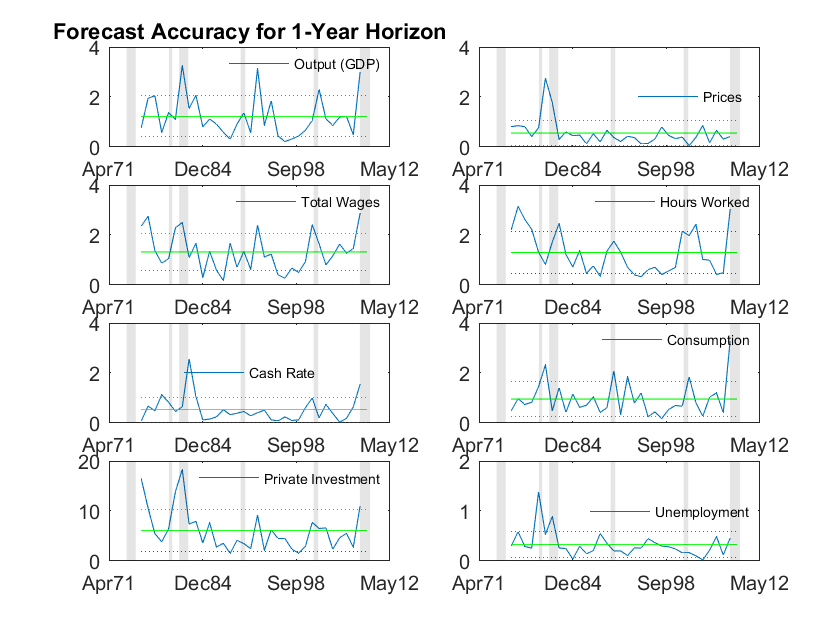

mFError = NaN(size(FError));
sFError = NaN(size(FError));
for i = 1:n
    mFError(:,i) = nanmean(FError(:,i));
    sFError(:,i) = nanstd(FError(:,i));
end

for i = 1:n
    subplot(ceil(n/2),2,i,'align');
    plot(FDates,FError(:,i));
    hold on
    plot(FDates,mFError(:,i),'g');
    plot(FDates,[mFError(:,i) - sFError(:,i),mFError(:,i) + sFError(:,i)],':r');
    recessionplot;
    dateaxis('x',12);
    if i == 1
        title(['\bfForecast Accuracy for ' sprintf('%g',Horizon/4) '-Year Horizon']);
    end
    h = legend(YSeries{i},'Location','best');
    h.FontSize = 7;
    h.Box = 'off';
    hold off
end

With the exception of private investment, forecasts tend to remain within plus or minus 2% of realized values over a one-year horizon. Errors increase around recessions, suggesting that some effects are absent from, or inadequately represented by, the linear specification.

## Recovery Outlook at Year-End 2008

Estimation through the end of 2008 assesses the recovery trajectory implied by the model following the financial crisis. The VAR(2) is estimated over 1959–2008 and projects the eight macroeconomic series five years ahead.

Actual observations are shown as green dots. The blue line represents the mean forecast, with dotted red lines marking one standard deviation above and below it.

nAR = 2;

% Set up date range

StartDate = lbusdate(1959,3);
EndDate = lbusdate(2008,12);

if StartDate < dates(1)
    error('usmacro:InsufficientHistory', ...
        'The estimation start precedes available data, which begin on %s.', ...
        string(datetime(dates(1),'ConvertFrom','datenum'),'dd-MMM-yyyy'));
end
if EndDate > dates(end)
    error('usmacro:InsufficientCoverage', ...
        'The estimation endpoint exceeds available data, which end on %s.', ...
        string(datetime(dates(end),'ConvertFrom','datenum'),'dd-MMM-yyyy'));
end

% Locate indexes in data for specified date range

iStart = find(StartDate <= dates,1);
if iStart < 1
    iStart = 1;
end
iEnd = find(EndDate <= dates,1);
if iEnd > numel(dates)
    iEnd = numel(dates);
end

% Set up data for estimation

D1 = dates(iStart:iEnd,:);			% dates for specified date range
if iStart > 1
    Y0 = Y(1:iStart-1,:);			% presample data
else
    Y0 = [];
end
Y1 = Y(iStart:iEnd,:);				% estimation data

% Set up model and estimate coefficients

Spec = vgxset('n', n, 'Constant', true, 'nAR', nAR, 'Series', YSeries, 'Info', YInfo);

Spec = vgxvarx(Spec, Y1, [], Y0);


% Do forecasts

FT = 20;
FD = Example_QuarterlyDates(dates(iEnd), FT);

[FY, FYCov] = vgxpred(Spec, FT, [], Y1);

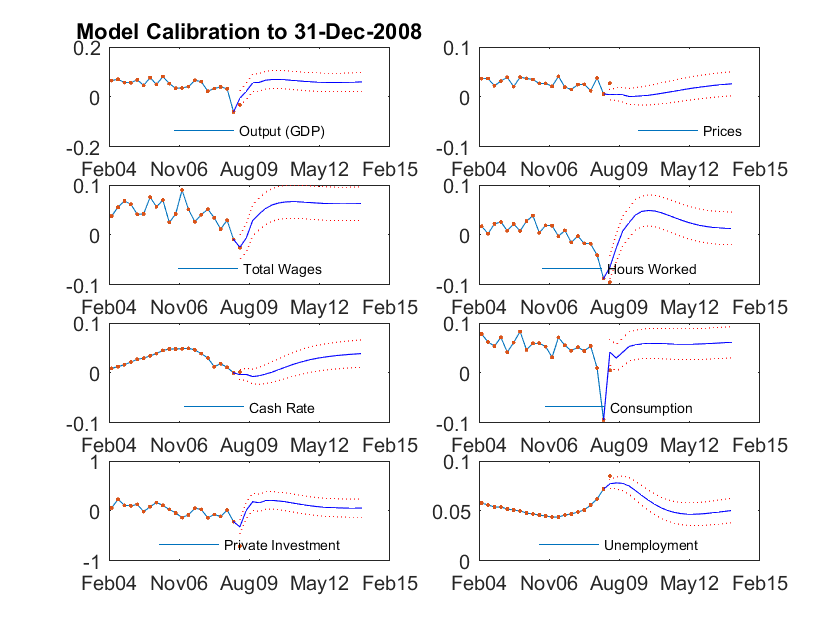

FYSigma = zeros(size(FY));
for t = 1:FT
    FYSigma(t,:) = sqrt(diag(FYCov{t}))';
end

Hw = 20;                                    % number of historical quarters to display
Fw = 20;                                    % number of forecast quarters to display
Ow = max(0,min(Fw,(size(Y,1) - iEnd)));     % overlap between historical and forecast data

clf;

for i = 1:n
    subplot(ceil(n/2),2,i,'align');
    plot(D1(end-Hw+1:end),Y1(end-Hw+1:end,i));
    hold on
    scatter(dates(iEnd-Hw+1:iEnd+Ow),Y(iEnd-Hw+1:iEnd+Ow,i),'.');
    plot([D1(end); FD],[Y1(end,i); FY(:,i)],'b');
    plot(FD,[FY(:,i) - FYSigma(:,i), FY(:,i) + FYSigma(:,i)],':r');
    dateaxis('x',12);
    if i == 1
        title(['\bfModel Calibration to ' sprintf('%s',datestr(dates(iEnd),1))]);
    end
    h = legend(YSeries{i},'Location','best');
    h.FontSize = 7;
    h.Box = 'off';
    hold off
end

The year-end 2008 projections suggest a recovery beginning during 2009. Output increases alongside interest rates and inflation, while unemployment declines gradually. The implied improvement in household conditions therefore lags the broader recovery.

Alternative estimation endpoints provide additional historical context. At a year-end 2006 estimation endpoint, the model projects a small decline in real GDP (nominal GDP net of the GDP deflator), a modest reduction in hours worked, and a slight rise in unemployment. These projections point to a slowdown or mild recession from the perspective of year-end 2006.

## Outlook at the Latest Available Observation

Re-estimating the same specification at the end of the observation period shows how additional information changes the recovery outlook. In the historical sample, this comparison extends the year-end 2008 assessment through 2009 Q1, capturing the next quarter of the downturn.

nAR = 2;

% Set up date range

StartDate = lbusdate(1959,3);
EndDate = dates(end);

if StartDate < dates(1)
    error('usmacro:InsufficientHistory', ...
        'The estimation start precedes available data, which begin on %s.', ...
        string(datetime(dates(1),'ConvertFrom','datenum'),'dd-MMM-yyyy'));
end
if EndDate > dates(end)
    error('usmacro:InsufficientCoverage', ...
        'The estimation endpoint exceeds available data, which end on %s.', ...
        string(datetime(dates(end),'ConvertFrom','datenum'),'dd-MMM-yyyy'));
end

% Locate indexes in data for specified date range

iStart = find(StartDate <= dates,1);
if iStart < 1
    iStart = 1;
end
iEnd = find(EndDate <= dates,1);
if iEnd > numel(dates)
    iEnd = numel(dates);
end

% Set up data for estimation

D1 = dates(iStart:iEnd,:);			% dates for specified date range
if iStart > 1
    Y0 = Y(1:iStart-1,:);			% presample data
else
    Y0 = [];
end
Y1 = Y(iStart:iEnd,:);				% estimation data

% Set up model and estimate coefficients

Spec = vgxset('n', n, 'Constant', true, 'nAR', nAR, 'Series', YSeries, 'Info', YInfo);

Spec = vgxvarx(Spec, Y1, [], Y0);


% Do forecasts

FT = 20;
FD = Example_QuarterlyDates(dates(iEnd), FT);

[FY, FYCov] = vgxpred(Spec, FT, [], Y1);

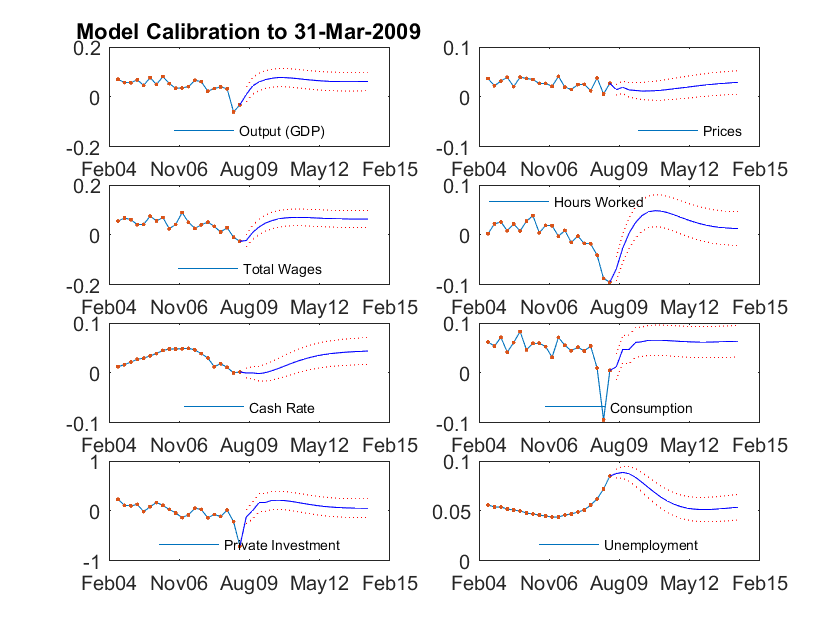

FYSigma = zeros(size(FY));
for t = 1:FT
    FYSigma(t,:) = sqrt(diag(FYCov{t}))';
end

Hw = 20;                                    % number of historical quarters to display
Fw = 20;                                    % number of forecast quarters to display
Ow = max(0,min(Fw,(size(Y,1) - iEnd)));     % overlap between historical and forecast data

clf;

for i = 1:n
    subplot(ceil(n/2),2,i,'align');
    plot(D1(end-Hw+1:end),Y1(end-Hw+1:end,i));
    hold on
    scatter(dates(iEnd-Hw+1:iEnd+Ow),Y(iEnd-Hw+1:iEnd+Ow,i),'.');
    plot([D1(end); FD],[Y1(end,i); FY(:,i)],'b');
    plot(FD,[FY(:,i) - FYSigma(:,i), FY(:,i) + FYSigma(:,i)],':r');
    dateaxis('x',12);
    if i == 1
        title(['\bfModel Calibration to ' sprintf('%s',datestr(dates(iEnd),1))]);
    end
    h = legend(YSeries{i},'Location','best');
    h.FontSize = 7;
    h.Box = 'off';
    hold off
end

Comparing these projections with the year-end 2008 outlook indicates how subsequent information changes the expected trajectory. The backtest suggests reasonable accuracy over about one year, implying that realized values should fall within the one-standard-deviation forecast bands over the next four quarters.

## Impulse Response Analysis

Impulse responses assess how a disturbance propagates through the system, providing a *ceteris paribus* sensitivity analysis relevant to policy questions. Each row represents a one-standard-deviation impulse to a series; each column shows the projected response of a model variable. Responses are expressed as percentage deviations from the initial state.

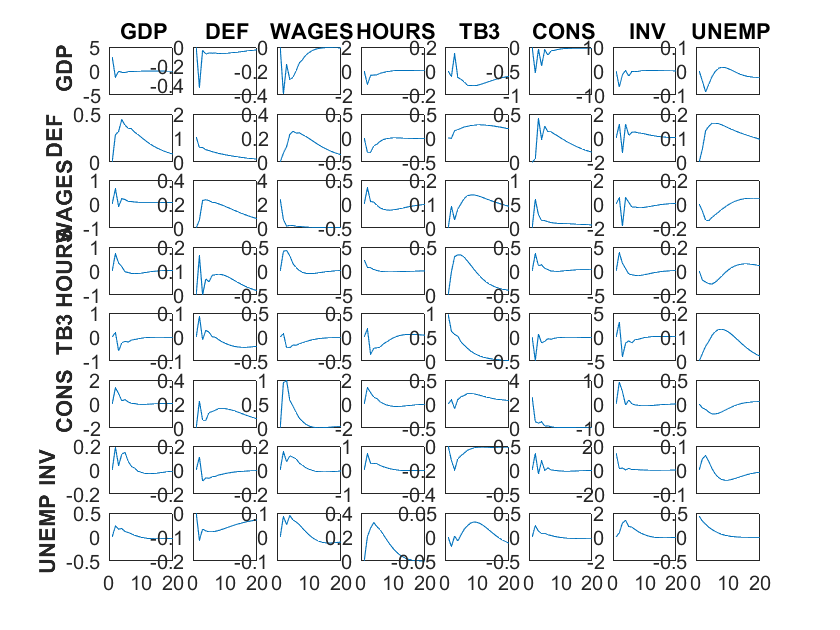

Impulses = YAbbrev;
Responses = YAbbrev;

W0 = zeros(FT, n);

clf;

ii = 0;
for i = 1:n
    WX = W0;
    WX(1,i) = sqrt(Spec.Q(i,i));
    YX = 100*(vgxproc(Spec, WX, [], Y1) - vgxproc(Spec, W0, [], Y1));
    for j = 1:n
        ii = ii + 1;
        subplot(n,n,ii,'align');
        plot(YX(:,j));
        if i == 1
            title(['\bf ' Responses{j}]);
        end
        if j == 1
            ylabel(['\bf ' Impulses{i}]);
        end
        ax = gca;
        if i == n
            ax.XTickMode = 'auto';
        else
            ax.XTick = [];
        end
    end
end

## Real GDP Forecast

The real GDP projection combines the output and price forecasts from the model estimated through the latest available observation. A trend fitted to the preceding 30 years of real GDP provides a long-term benchmark for the projected trajectory.

iY1 = iY(iStart:iEnd,:);

% Simulate forecasts of cumulative values of model time series

NumPaths = 1000;
iFY = vgxsim(Spec, FT, [], Y1, [], NumPaths);

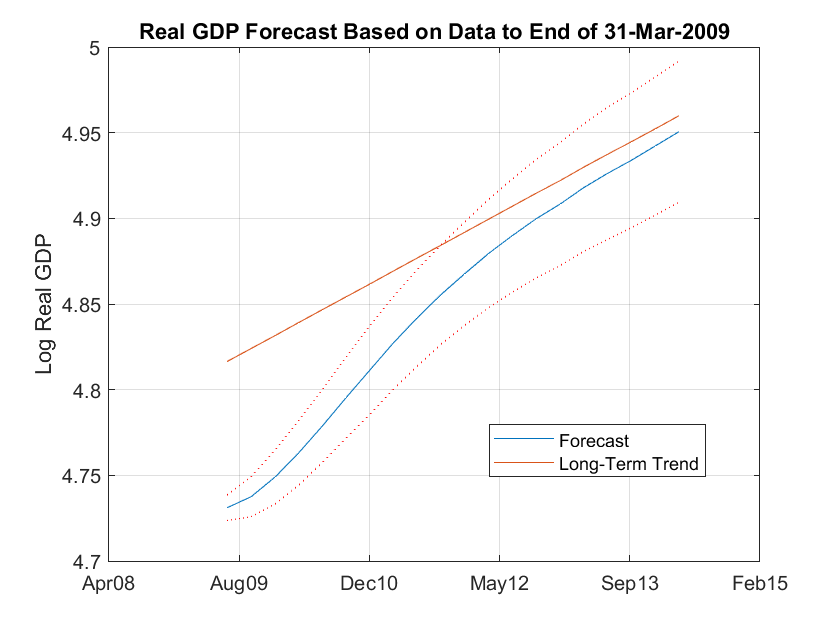

iFY = repmat(iY1(end,:),[FT,1,NumPaths]) + 0.25*cumsum(iFY);
iFY = iFY(:,1,:) - iFY(:,2,:);
FGDP = mean(iFY,3);
FGDPSigma = std(iFY,0,3);
FGDP0 = GDP(iEnd) - DEF(iEnd);

w = 120;
H = [ ones(w,1) (1:w)' ];
trendParam = H \ (GDP(iEnd - w + 1:iEnd) - DEF(iEnd - w + 1:iEnd));
trendFGDP = [ ones(FT,1) w + (1:FT)' ] * trendParam;

clf;

plot(FD, [FGDP, trendFGDP]);
hold on
plot(FD, [FGDP - FGDPSigma, FGDP + FGDPSigma],':r');
title(['\bfReal GDP Forecast Based on Data to End of ' sprintf('%s',datestr(dates(iEnd),1))]);
dateaxis('x',12);
legend('Forecast','Long-Term Trend','Location','Best');
grid on;
ylabel('Log Real GDP');

A forecast that begins below trend and subsequently converges toward it implies growth above the trend rate during the recovery. The late-2008 and early-2009 projections exhibit this pattern, suggesting a strong recovery during 2010.

## Assessment

The eight-variable VAR provides reasonably accurate one-year forecasts for most series in the historical backtest, with private investment showing greater errors. Forecast performance deteriorates around recessions, indicating effects that the linear specification does not fully capture. The late-2008 and early-2009 projections imply recovering output followed by a more gradual improvement in unemployment, while convergence of real GDP toward its long-term trend suggests stronger growth during 2010.

## References

- M. Del Negro, F. Schorfheide, F. Smets, and R. Wouters (2007), "On the Fit of New Keynesian Models," *Journal of Business & Economic Statistics*, Vol. 25, No. 2, pp. 123-162.

- FRED, St. Louis Federal Reserve, Federal Reserve Economic Database,  [http://research.stlouisfed.org/fred2/](http://research.stlouisfed.org/fred2/).

- M. Kimball (1995), "The Quantitative Analytics of the Basic Neomonetarist Model", *Journal of Money, Credit, and Banking*, *Part 2: Liquidity, Monetary Policy, and Financial Intermediation*, Vol. 27, No. 4, pp. 1241-1277.

- H. Lutkepohl (2006). *New Introduction to Multiple Time Series Analysis*, Springer.

- H. Lutkepohl and M. Kratzig (2004). *Applied Time Series Econometrics*, Cambridge University Press.

- NBER, National Bureau of Economic Research, *Business Cycle Expansions and Contractions*,  [http://www.nber.org/cycles/cyclesmain.html](http://www.nber.org/cycles/cyclesmain.html).

- F. Smets and R. Wouters (2002), *An Estimated Stochastic Dynamic General Equilibrium Model of the Euro Area*, European Central Bank, Working Paper Series, No. 171. Also in *Journal of the European Economic Association*, Vol. 1, No. 5, 2003, pp. 1123-1175.

- F. Smets and R. Wouters (2004), *Comparing Shocks and Frictions in US and Euro Area Business Cycles: A Bayesian DSGE Approach*, European Central Bank, Working Paper Series, No. 391. Also in  *Journal of Applied Econometrics*, Vol. 20, No. 1, 2005, pp. 161-183.

- F. Smets and R. Wouters (2007), *Shocks and Frictions in US Business Cycles: A Bayesian DSGE Approach*, European Central Bank, Working Paper Series, No. 722. Also in *American Economic Review*, Vol. 97, No. 3, 2007, pp. 586-606.

*Copyright 2009-2016 The MathWorks, Inc.*